% FSI: 2DOF mechanical oscillator - State-Space system and Transfer Function
% Filip Kšica, © VUT 2025

clc;clear all;close all;

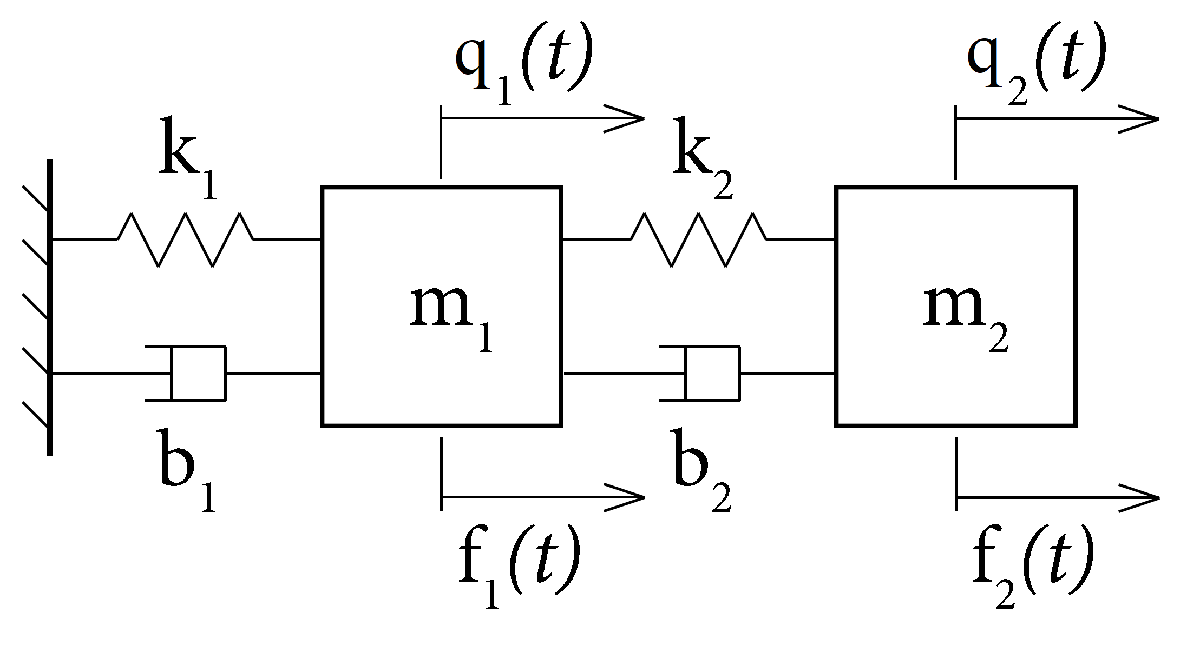

## Equations of motion:

These equations have been assembled using free body diagram of the given system and d'Alembert principle.


$${\ddot{q} }_1 =-\frac{b_1 +b_2 }{m_1 }{\dot{q} }_1 +\frac{b_2 }{m_1 }{\dot{q} }_2 -\frac{k_1 +k_2 }{m_1 }q_1 +\frac{k_2 }{m_1 }q_2 +\frac{f_1 \left(t\right)}{m_1 }$$



$${\ddot{q} }_2 =-\frac{b_2 }{m_2 }{\dot{q} }_2 +\frac{b_2 }{m_2 }{\dot{q} }_1 -\frac{k_2 }{m_2 }q_2 +\frac{k_2 }{m_2 }q_1 +\frac{f_2 \left(t\right)}{m_2 }$$


## State-space eqations:

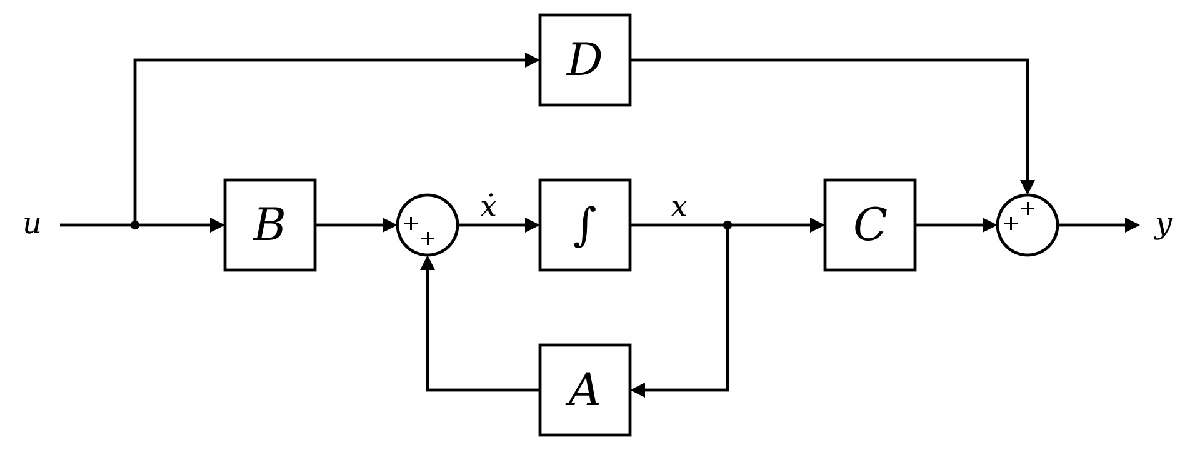

The general equations describing the behavior of the state-space system are 


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}+\textrm{Du}
\end{array}$$


where $x$ is the state vector,$y$ is the output vector, $u$ is the input vector, $A$ is the state matrix, $B$ is the input matrix, $C$ is the output matrix and $D$ is the feedforward matrix. The state vector$x$ consists of  state variables $x_1 -x_4$, which represent displacement and velocity of individual masses in the original system, 

$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack$where $\left\lbrace \begin{array}{c}
x_1 =q_1 \\
x_2 ={\dot{q} }_1 \\
x_3 =q_2 \\
x_4 ={\dot{q} }_2 
\end{array}\right.$

To assemble the matrices $A,B,C\;\textrm{and}\;D$, equation of motions (second order differential equations) have to be split into differential equations of first order only using newly defined state vector $x$ and no longer using original physical coordinates $q$ (similar procedure as with ode45 solver). This is necessary because the state-space equations contain only the first derivation of the state vector.


$${\dot{x} }_1 =x_2$$



$${\dot{x} }_2 =-\frac{b_1 +b_2 }{m_1 }x_2 +\frac{b_2 }{m_1 }x_4 -\frac{k_1 +k_2 }{m_1 }x_1 +\frac{k_2 }{m_1 }x_3 +\frac{f_1 \left(t\right)}{m_1 }$$



$${\dot{x} }_3 =x_4$$



$${\dot{x} }_4 =-\frac{b_2 }{m_2 }x_4 +\frac{b_2 }{m_2 }x_2 -\frac{k_2 }{m_2 }x_3 +\frac{k_2 }{m_2 }x_1 +\frac{f_2 \left(t\right)}{m_1 }$$


The output vector$y$ can contain any of the states $x$, therefore will have the same dimension


$$y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 \\
y_4 
\end{array}\right\rbrack$$


There are up to two inputs to the system representing forces on each fo the masses, therefore the dimension of the input vector is

$u=\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$where $\left\lbrace \begin{array}{c}
u_1 =f_1 \left(t\right)\\
u_2 =f_2 \left(t\right)
\end{array}\right.$

## Assembly of the state-space matrices:

In this step, the given state-space equations are used to assemble state-space matrices. First equation  $\dot{x} =\textrm{Ax}+\textrm{Bu}$ will use the abovementioned set of first order differential equations


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 \\
{\dot{x} }_3 \\
{\dot{x} }_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{\left(k_1 +k_2 \right)}{m_1 } & -\frac{\left(b_1 +b_2 \right)}{m_1 } & \frac{k_2 }{m_1 } & \frac{b_2 }{m_1 }\\
0 & 0 & 0 & 1\\
\frac{k_2 }{m_2 } & \frac{b_2 }{m_2 } & -\frac{k_2 }{m_2 } & -\frac{b_2 }{m_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{m_1 } & 0\\
0 & 0\\
0 & \frac{1}{m_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


Second equation $y=\textrm{Cx}+\textrm{Du}$ just gives us the relation between states and outputs of the system, and matrix $C$ contains ones in those lines where the state is forwarded to output. Feedforward matrix $D$ is for majority of cases a zero matrix (no direct connection between input and output of the system). For the case where outputs contain only displacement (states $x_1$ and $x_3$), the form is


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 \\
y_4 
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


If velocities are included in outputs of the system, the form would change to 


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 \\
y_4 
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


## Input parameters

**Note:** Let's set the parameters to simulate behavior of a tuned mass damper.

% h = 60;
% d = 2;
% t = 12*(10^(-3));
% ro = 7850;
% V = h*((pi*(d/2)^2)-(pi*((d/2)-t)^2));
% m1 = ro*V;

m1 = 45000;                 % [kg] mass
mi = 0.03;
m2 = mi*m1;                   % [kg] mass

Q = 100;                     % [-] quality factor, Q = 1/(2*xi), Q_crit = 0.5
freq_0 = 0.6;                % [Hz] natural frequency
omega_0 = 2*pi*freq_0;      % [rads-1] natural frequency

b1 = (2*m1*omega_0)/(2*Q);  % [Nsm-1] damping
k1 = omega_0^2*m1;          % [Nm-1] stiffness
% b2 = (2*m2*omega_0)/(2*Q);  % [Nsm-1] damping
k2 = omega_0^2*m2;          % [Nm-1] stiffness
zeta2 = sqrt((3*mi)/(8*(1+mi)^3));
bc = 2*sqrt(k2*m2);
b2 = zeta2*bc;

## Excitation

% Input selection
is_1 = 1;       % first input selection, 1 - harmonic, 2 - impulse
is_2 = 1;       % second input selection, 1 - harmonic, 2 - impulse

% Force amplitudes
F_1 = 0.25;
F_2 = ((1+mi)/mi)*F_1;
Redukce = (mi*Q)/(1+mi*Q);
F_1 = 0.25*(1-Redukce);
F_2 = ((1+mi)/mi)*F_1;

% Harmonic
bias_1 = 0;
f_1 = freq_0;
omega_1 = 2*pi*f_1;
phase_1 = 0;

bias_2 = 0;
f_2 = f_1/(1+mi);
omega_2 = 2*pi*f_2;
phase_2 = 0;

% Impulse
t_1 = 0.25;
t_2 = 0;

## Initial conditions

**Note: **Initial conditions for transfer functions are automatically preset to zero. 

**Note:** State-Space models allow the input of non-zero initial conditions.

x_10 = 0;%5e-3;                   % [m] initial displacement
v_10 = 0;                   % [ms-1] initial velocity
x_20 = 0;%-3e-3;                   % [m] initial displacement
v_20 = 0;                   % [ms-1] initial velocity

## Eigenvalues and eigenvectors of the system

% Mass and stiffness matrices
M2 = [m1 0;0 m2];
K2 = [k1+k2 -k2;-k2 k2];

% Eigenvalues and eigenvectors
[eigenvectors_2DOF, eigenvalues_2DOF] = eig(K2,M2);    % similar to eig(inv(K2)*M2)

f_01 =  sqrt(eigenvalues_2DOF(1,1))./(2*pi);           % [Hz] first eigenfrequency
f_02 =  sqrt(eigenvalues_2DOF(2,2))./(2*pi);           % [Hz] second eigenfrequency

% Listing
disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Mass and stiffness matrices of 2DOF system:')

Mass and stiffness matrices of 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


M2

M2 =        45000           0
           0        1350


K2

K2 = 1.0e+05 *

    6.5874   -0.1919
   -0.1919    0.1919



disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Spectral matrix of 2DOF system:')

Spectral matrix of 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


eigenvalues_2DOF

eigenvalues_2DOF =    11.9546         0
         0   16.8963



disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Modal matrix of 2DOF system:')

Modal matrix of 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


eigenvectors_2DOF

eigenvectors_2DOF =    -0.0032   -0.0035
   -0.0201    0.0184



disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Eigenfrequencies of individual 1DOF systems:')

Eigenfrequencies of individual 1DOF systems:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


fprintf('Eigenfrequency (undamped) of first system: %.3f Hz \n',sqrt(k1/m1)/(2*pi))

Eigenfrequency (undamped) of first system: 0.600 Hz 


fprintf('Eigenfrequency (undamped) of second system: %.3f Hz \n',sqrt(k2/m2)/(2*pi))

Eigenfrequency (undamped) of second system: 0.600 Hz 



disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Eigenfrequencies of 2DOF system:')

Eigenfrequencies of 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


fprintf('1. Eigenfrequency (undamped): %.3f Hz \n',f_01)

1. Eigenfrequency (undamped): 0.550 Hz 


fprintf('2. Eigenfrequency (undamped): %.3f Hz \n',f_02)

2. Eigenfrequency (undamped): 0.654 Hz 



disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Eigenvectors of 2DOF system:')

Eigenvectors of 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


fprintf('1. Eigenvector: %.3f %.3f \n',eigenvectors_2DOF(1,1),eigenvectors_2DOF(2,1))

1. Eigenvector: -0.003 -0.020 


fprintf('2. Eigenvector: %.3f %.3f \n',eigenvectors_2DOF(1,2),eigenvectors_2DOF(2,2))

2. Eigenvector: -0.003 0.018 


## State-Space System

A2 = [  0               1               0           0           ;...
        -(k1+k2)/m1     -(b1+b2)/m1     k2/m1       b2/m1       ;...
        0               0               0           1           ;...
        k2/m2           b2/m2           -k2/m2      -b2/m2      ];
B2 = [  0   	0       ;...    
        1/m1  0       ;...
        0       0       ;...
        0       1/m2  ];
C2 = [  1   0   0   0   ;...
        0   0   1   0   ];
D2 = zeros(2,2);

% Listing
disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('State-Space matrices of 2DOF system:')

State-Space matrices of 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


A2

A2 =          0    1.0000         0         0
  -14.6386   -0.0607    0.4264    0.0230
         0         0         0    1.0000
   14.2122    0.7650  -14.2122   -0.7650


B2

B2 = 1.0e-03 *

         0         0
    0.0222         0
         0         0
         0    0.7407


C2

C2 =      1     0     0     0
     0     0     1     0


D2

D2 =      0     0
     0     0


## Transfer Function

**Note:** For 2DOF system, a total of 4 individual transfer functions will be given (number of combinations between 2 inputs and 2 outputs). That is:


$${\textrm{TF}}_1 =\frac{X_1 }{F_1 }$$
  
$${\textrm{TF}}_2 =\frac{X_2 }{F_1 }$$
  
$${\textrm{TF}}_3 =\frac{X_1 }{F_2 }$$
  
$${\textrm{TF}}_4 =\frac{X_2 }{F_2 }$$


**Note:** Relation between transfer function and state space system can be written as


$$\textrm{TF}\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=C{\left(\textrm{sI}-A\right)}^{-1} B+D$$


**Note:** In the command *ss2tf*, the last parameter *io* in bracket defines the *i*-th input.

SS2DOF = ss(A2,B2,C2,D2);
[num_2DOF_1, den_2DOF_1] = ss2tf(A2,B2,C2,D2,1);
disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Transfer functions for 2DOF system:')

Transfer functions for 2DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


tf_2DOF_1 = tf(num_2DOF_1(1,:), den_2DOF_1)


tf_2DOF_1 =
 
     2.222e-05 s^2 + 1.7e-05 s + 0.0003158
  --------------------------------------------
  s^4 + 0.8257 s^3 + 28.88 s^2 + 11.41 s + 202
 
Continuous-time transfer function.
Model Properties


tf_2DOF_2 = tf(num_2DOF_1(2,:), den_2DOF_1)


tf_2DOF_2 =
 
             1.7e-05 s + 0.0003158
  --------------------------------------------
  s^4 + 0.8257 s^3 + 28.88 s^2 + 11.41 s + 202
 
Continuous-time transfer function.
Model Properties



[num_2DOF_2, den_2DOF_2] = ss2tf(A2,B2,C2,D2,2);
tf_2DOF_3 = tf(num_2DOF_2(1,:), den_2DOF_2)


tf_2DOF_3 =
 
             1.7e-05 s + 0.0003158
  --------------------------------------------
  s^4 + 0.8257 s^3 + 28.88 s^2 + 11.41 s + 202
 
Continuous-time transfer function.
Model Properties


tf_2DOF_4 = tf(num_2DOF_2(2,:), den_2DOF_2)


tf_2DOF_4 =
 
     0.0007407 s^2 + 4.493e-05 s + 0.01084
  --------------------------------------------
  s^4 + 0.8257 s^3 + 28.88 s^2 + 11.41 s + 202
 
Continuous-time transfer function.
Model Properties


## Bode diagram

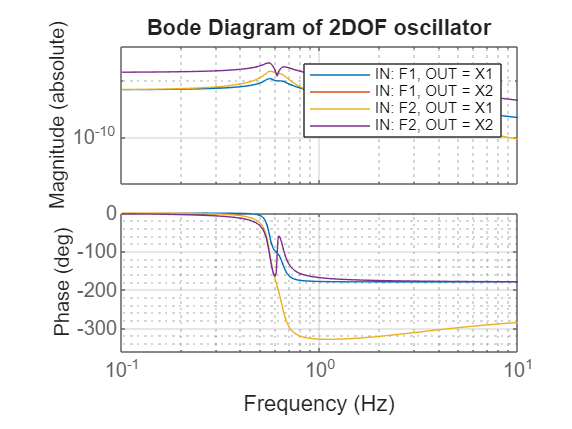

n_freq = 0.6;
freq_bode = logspace(1,3,n_freq);
bode_opt = bodeoptions('cstprefs');     % initialize plot options in the Control System and System Identification Toolbox
bode_opt.FreqUnits = 'Hz';              % set frequency units to Hz (rads-1 is default)
bode_opt.MagUnits = 'abs';
bode_opt.MagScale = 'log';

figure;set(gcf,'color','w');
bode(tf_2DOF_1,freq_bode,bode_opt);hold on
bode(tf_2DOF_2,freq_bode,bode_opt);
bode(tf_2DOF_3,freq_bode,bode_opt);
bode(tf_2DOF_4,freq_bode,bode_opt);
grid on; grid minor
xlim([-0 1e1])
title('Bode Diagram of 2DOF oscillator')
legend('IN: F1, OUT = X1','IN: F1, OUT = X2','IN: F2, OUT = X1','IN: F2, OUT = X2')
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 10, 'FontWeight', 'bold')

## Time-domain response simulation - Simulink

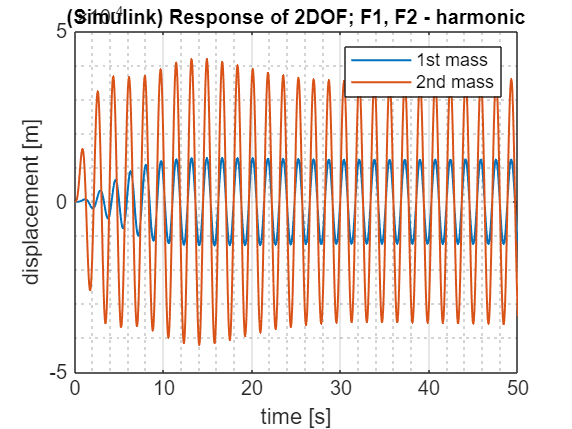

% Using Simulink
t_simend = 50;                   % [s] end time of simulation
simOut = sim('FSI_2DOF_SS_TF_Simulink','StopTime',num2str(t_simend));

% Save simulated data into variables
t_sim = simOut.get('t_sim');
x1_2DOF = simOut.get('x1_2DOF');
x2_2DOF = simOut.get('x2_2DOF');
F1_2DOF = simOut.get('F1_2DOF');
F2_2DOF = simOut.get('F2_2DOF');

% Plot simulated time-domain response of 2DOF
figure;set(gcf,'color','w');
plot(t_sim,[x1_2DOF x2_2DOF],'LineWidth',1);
grid on; grid minor
xlabel('time [s]')
ylabel('displacement [m]')
legend('1st mass','2nd mass')
if is_1 == 1 && is_2 == 1
    title('(Simulink) Response of 2DOF; F1, F2 - harmonic','FontSize',10,'FontWeight','bold')
elseif is_1 == 1 && is_2 == 2
    title('(Simulink) Response of 2DOF; F1 - harmonic, F2 - impulse','FontSize',10,'FontWeight','bold')
elseif is_1 == 2 && is_2 == 1
    title('(Simulink) Response of 2DOF; F1 - impulse, F2 - harmonic','FontSize',10,'FontWeight','bold')
elseif is_1 == 2 && is_2 == 2
    title('(Simulink) Response of 2DOF; F1, F2 - impulse','FontSize',10,'FontWeight','bold')
    
end

## Time-domain response simulation - lsim

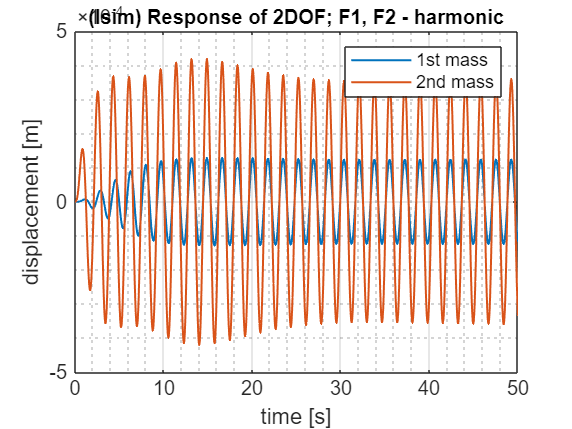

% Using lsim function
x1_F1_lsim = lsim(tf_2DOF_1,F1_2DOF,t_sim);
x2_F1_lsim = lsim(tf_2DOF_2,F1_2DOF,t_sim);
x1_F2_lsim = lsim(tf_2DOF_3,F2_2DOF,t_sim);
x2_F2_lsim = lsim(tf_2DOF_4,F2_2DOF,t_sim);

x1_lsim = x1_F1_lsim + x1_F2_lsim; % X1/F1 + X1/F2
x2_lsim = x2_F1_lsim + x2_F2_lsim; % X2/F1 + X2/F2


% Plot simulated time-domain response of 2DOF
figure;set(gcf,'color','w');
plot(t_sim,[x1_lsim x2_lsim],'LineWidth',1);
grid on; grid minor
xlabel('time [s]')
ylabel('displacement [m]')
legend('1st mass','2nd mass')
if is_1 == 1 && is_2 == 1
    title('(lsim) Response of 2DOF; F1, F2 - harmonic','FontSize',10,'FontWeight','bold')
elseif is_1 == 1 && is_2 == 2
    title('(lsim) Response of 2DOF; F1 - harmonic, F2 - impulse','FontSize',10,'FontWeight','bold')
elseif is_1 == 2 && is_2 == 1
    title('(lsim) Response of 2DOF; F1 - impulse, F2 - harmonic','FontSize',10,'FontWeight','bold')
elseif is_1 == 2 && is_2 == 2
    title('(lsim) Response of 2DOF; F1, F2 - impulse','FontSize',10,'FontWeight','bold')
    
end